This script is used to generate the figures used in the following manuscript:

Author: Jonathan P. Platt

Data needed for generating figures:

Ca1_epochs.mat (github repo)

Figure1_ProcessedData.nwb

Figure2_ProcessedData.nwb

Figure5_ProcessedData.nwb

Mendeley Data Repo: NWB datasets

DOI:10.17632/7gn6dj89t3.1

Version 1 (current): Initial dataset for generating figures 1, 2 and 5.

Cite this dataset:

Platt, Jonathan P; Simoes De Souza, Fabio; Restrepo, Diego; Ma, Ming (2024), “Sequential activity of CA1 hippocampal cells constitutes a temporal memory map for associative learning in mice”, Mendeley Data, V1, doi: 10.17632/7gn6dj89t3.1

%clean up
clear
close all
clc

Figure 1.

if exist('Figure1_ProcessedData.nwb', 'file') == 2
    Figure1_data = nwbRead("Figure1_ProcessedData.nwb",'ignorecache');
else
    qanswer = questdlg('Please select the location of Figure1_ProcessedData.nwb', ...
        'Choose file location', ...
        'Select','Exit','Select');
    switch qanswer
        case 'Select'
            [fname, fpath, eew] = uigetfile('*.nwb');
            fullpathtofile = strcat(fpath,fname);
            Figure1_data = nwbRead(fullpathtofile,'ignorecache');
        case 'Exit'
            return
    end
end

handles.dropcData.epochIndex = 172;
handles.dropcData.epochEvent = Figure1_data.processing.get('EpochEvent_Values').dynamictable.get('ProcessVar').vectordata.get('epochEvent').data.load'; %172X1
handles.dropcData.epochTypeOfOdor = Figure1_data.processing.get('EpochOdor_Values').dynamictable.get('ProcessVar').vectordata.get('epochTypeOfOdor').data.load'; %172X1
handles.dropcProg.splusOdor = 1;
handles.dropcData.epochTime = Figure1_data.processing.get('EpochTime_Values').dynamictable.get('ProcessVar').vectordata.get('epochTime').data.load'; %172X1
traces = Figure1_data.processing.get('Trace_Values').dynamictable.get('ProcessVar').vectordata.get('trace_var').data.load; %2400X153
time = Figure1_data.processing.get('Time_Values').dynamictable.get('ProcessVar').vectordata.get('time').data.load'; % 1X24000
epochs = Figure1_data.processing.get('Epoch_Values').dynamictable.get('ProcessVar').vectordata.get('epochVarable').data.load';

post_time=5; %The decoding model will be trained with all points in post_time sec interval starting post_shift secs after odor on
pre_time=5; %Used to calculate the decoding accuracy pre_time sec before post_shift
post_shift=0; %Set to 0 if you want to train with odor on points
dt_span=40; %Seconds shown before and after odor on in the figures
dt_p_threshold=4.2; %Time to be used after the odor on for the p_threshold t_test
acy_rate = 20000;
dt_before = 10;
no_odor_trials = 34;


F.1C

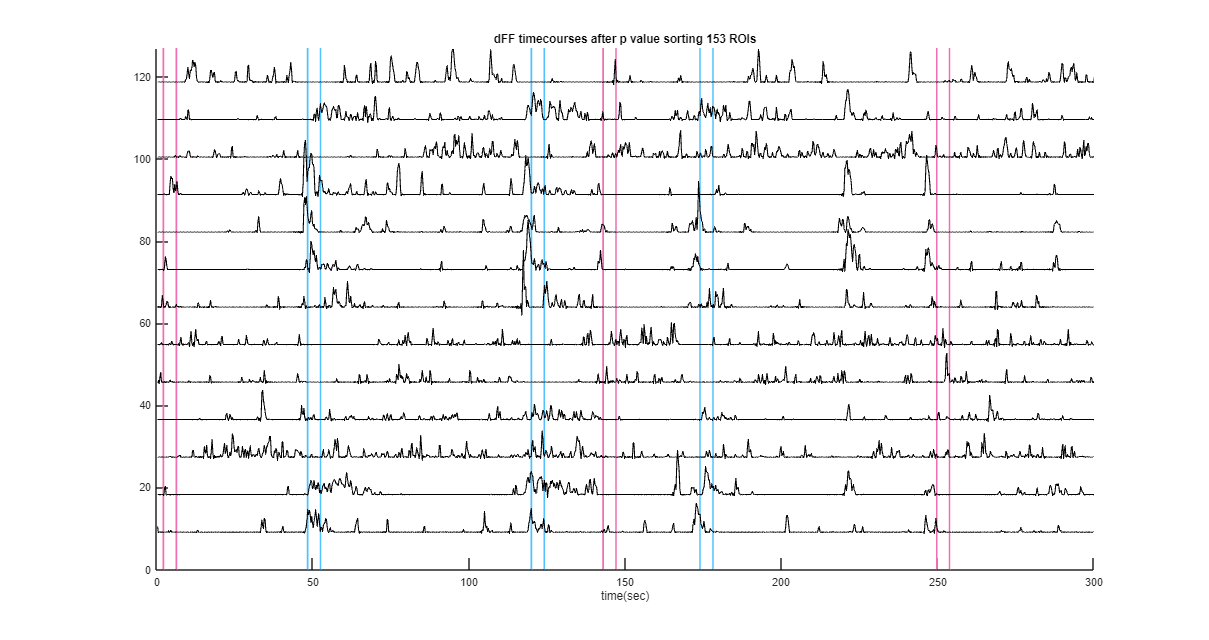

%{
The following will generate Figure 1C
%}
%Post points
% Nall=size(traces,1);
% dt=median(time(2:end)-time(1:end-1));
% ii_p_threshold=ceil(dt_p_threshold/dt);
% no_points_post=floor(post_time/dt);
% no_points_post_shift=floor(post_shift/dt);
% no_points_pre=floor(pre_time/dt);

y_shift=6*(prctile(traces(:),95)-prctile(traces(:),5));

%Post points
dt=median(time(2:end)-time(1:end-1));
ii_p_threshold=ceil(dt_p_threshold/dt);
no_points_post=floor(post_time/dt);
no_points_post_shift=floor(post_shift/dt);
no_points_pre=floor(pre_time/dt);


[~,~,dFFs_sp_per_trial_per_ROI,...
    dFFs_sm_per_trial_per_ROI,~,~,~,...
    ~,~,...
    ~,~,measurements_post,...
    ~,~,~,~...
    ,~,~,~,~] = ...
    drgCaImAn_parse_out_trials(dt, 40,epochs,no_points_post_shift,no_points_post,no_points_pre,traces,ii_p_threshold,no_odor_trials);


%Now let's limit the ROIs to those below p_threshold

p_values=ones(1,size(dFFs_sm_per_trial_per_ROI,2));
for iiROI=1:size(dFFs_sm_per_trial_per_ROI,2)
    dFF_sm=zeros(size(dFFs_sm_per_trial_per_ROI,1),size(dFFs_sm_per_trial_per_ROI,3));
    dFF_sm(:,:)=dFFs_sm_per_trial_per_ROI(:,iiROI,:);
    dFF_sp=zeros(size(dFFs_sp_per_trial_per_ROI,1),size(dFFs_sp_per_trial_per_ROI,3));
    dFF_sp(:,:)=dFFs_sp_per_trial_per_ROI(:,iiROI,:);

    [~,p_values(iiROI)]=ttest2(mean(dFF_sp,2),mean(dFF_sm,2));
end

no_traces=size(traces,1);


%Plot the trimmed traces sorted according to p values
to_sort=zeros(no_traces,2);
to_sort(:,1)=1:no_traces;
to_sort(:,2)=p_values;
sorted=sortrows(to_sort,2);
traces_sorted=zeros(no_traces,1);
traces_sorted(:,1)=sorted(:,1);

%time has the time for the dF/F traces(ROI,time)
figNo = 0;
figNo=figNo+1;
try
    close(figNo)
catch
end

hFig = figure(figNo);

set(hFig, 'units','normalized','position',[.05 .1 .85 .8])
hold on

%Plot the traces and do z normalization
%For S+ and S- plot odor on and reinforcement
for epoch=1:handles.dropcData.epochIndex
    %Epoch 2 is odor on, 3 is odor off
    plot_epoch=(handles.dropcData.epochEvent(epoch)==2)||(handles.dropcData.epochEvent(epoch)==3);
    if plot_epoch
        if handles.dropcData.epochTypeOfOdor(epoch)==handles.dropcProg.splusOdor
            plot([handles.dropcData.epochTime(epoch) handles.dropcData.epochTime(epoch)], [0 (no_traces+2)*y_shift],...
                'Color',[80/255 194/255 255/255],'LineWidth',1.5)
        else
            plot([handles.dropcData.epochTime(epoch) handles.dropcData.epochTime(epoch)], [0 (no_traces+2)*y_shift],...
                'Color',[238/255 111/255 179/255],'LineWidth',1.5)
        end
    end
end


for trNo=1:no_traces
    % for trNo=1:20
    plot(decimate(time,5),decimate(traces(traces_sorted(trNo),:),5)+y_shift*trNo,'-k','LineWidth',1)
end

%         ylim([-y_shift*0.2 (no_traces+2)*y_shift])
xlim([0 300])
ylim([0 127])
xlabel('time(sec)')
title(['dFF timecourses after p value sorting ' num2str(size(measurements_post,2)) ' ROIs'])

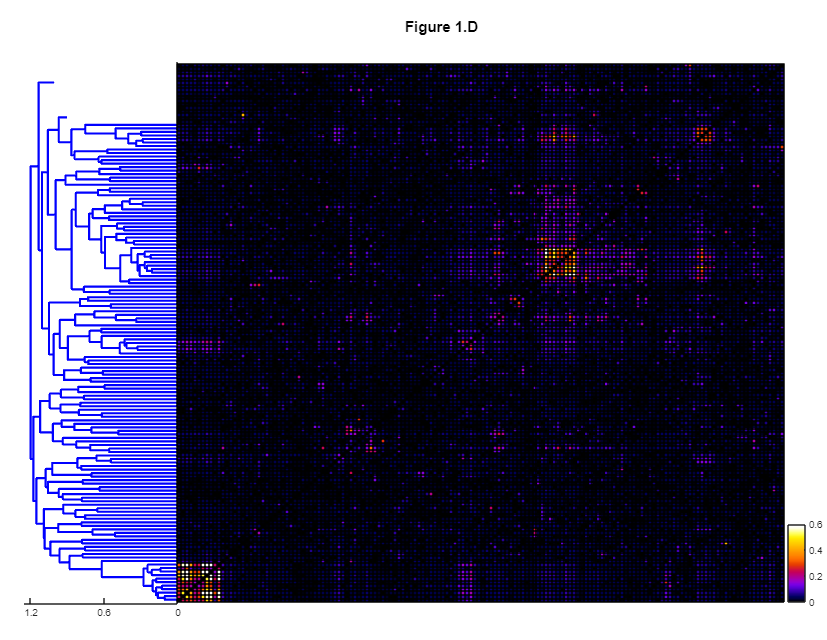


%{
The following will generate Figure 1.D
%}
FigOne = figure();
FigOne.Position(1) = FigOne.Position(1) + 500;
FigOne.Position(2) = FigOne.Position(2) + 400;
FigOne.Position(3) = FigOne.Position(3) + 500;
FigOne.Position(4) = FigOne.Position(4) + 400;

subplot(2,2,1:2)
text(.4,.5,'Figure 1.D','FontSize',14,'FontWeight','bold'); axis off
ax = gca;
ax.Position(1) = ax.Position(1) + 0.05;
ax.Position(2) = ax.Position(2) + 0.28;
ax.Position(4) = ax.Position(4) - 0.15;

for trace_nom=1:size(traces,1)
    traces(trace_nom,:)=traces(trace_nom,:)/std(traces(trace_nom,:));
end

%Calculate the crosscorrelations
croscorr_traces=abs(corrcoef(traces')); %please note that I am using the absolute value

%Set autocorrelations to zero
for ii=1:size(croscorr_traces,1)
    croscorr_traces(ii,ii)=0;
end
Z = linkage(croscorr_traces,'complete','correlation');
subplot(2,2,3)
ax = gca;
ax.Position(1) = ax.Position(1) - .1;
ax.Position(2) = ax.Position(2) - .053;
ax.Position(3) = ax.Position(3) - .15;
ax.Position(4) = ax.Position(4) + .505;
[H,T,outperm]=dendrogram(Z,0,'Orientation','left');
set(H,'LineWidth',2)
yticks([])
xticks([0 0.6 1.2])
xlim([0 1.25])

for ii=1:size(croscorr_traces,1)
    for jj=1:size(croscorr_traces,1)
        perm_croscorr_traces(ii,jj)=croscorr_traces(outperm(ii),outperm(jj));
    end
end

subplot(2,2,4)
ax = gca;
ax.Position(1) = ax.Position(1) - .356;
ax.Position(2) = ax.Position(2) - .05;
ax.Position(3) = ax.Position(3) + .40;
ax.Position(4) = ax.Position(4) + .5;
hold on
pcolor(perm_croscorr_traces)
colormap fire
clim([0 0.6])
ylim([1 153])
yticks([])
xlim([1 153])
xticks([])

cbOne = colorbar(ax,"eastoutside");
cbOne.Position(1) = cbOne.Position(1) + .05;
cbOne.Position(4) = cbOne.Position(4) - .72;

Figure 1.E

FigOneE = figure();
FigOneE.Position(1) = FigOneE.Position(1) + 700;
FigOneE.Position(2) = FigOneE.Position(2) + 400;
FigOneE.Position(3) = FigOneE.Position(3) + 700;
FigOneE.Position(4) = FigOneE.Position(4) + 400;
y_shift=6*(prctile(traces(:),95)-prctile(traces(:),5));
no_traces=size(traces,1);
hier_traces=zeros(size(traces,1),size(traces,2));

for trNo=1:no_traces
    hier_traces(trNo,:)=traces(outperm(trNo),:);
end

drg_pcolor(repmat(time',1,no_traces),repmat(1:no_traces,length(time),1),hier_traces')



colormap fire
shading interp
cmax=prctile(traces(:),99);
cmin=prctile(traces(:),1);
clim([cmin cmax]);

hold on
%Plot the traces and do z normalization
%For S+ and S- plot odor on and reinforcement
for epoch=1:handles.dropcData.epochIndex
    %Epoch 2 is odor on, 3 is odor off
    plot_epoch=(handles.dropcData.epochEvent(epoch)==2)||(handles.dropcData.epochEvent(epoch)==3);
    if plot_epoch
        if handles.dropcData.epochTypeOfOdor(epoch)==handles.dropcProg.splusOdor
            plot([handles.dropcData.epochTime(epoch) handles.dropcData.epochTime(epoch)], [0 (no_traces+2)*y_shift],...
                'Color',[80/255 194/255 255/255],'LineWidth',1.5)
        else
            plot([handles.dropcData.epochTime(epoch) handles.dropcData.epochTime(epoch)], [0 (no_traces+2)*y_shift],...
                'Color',[238/255 111/255 179/255],'LineWidth',1.5)
        end
    end
end


xlabel('Time (sec)')
ylabel('ROI number');
ylim([1 no_traces])
xlim([0 300])
title(['All dFF timecourses p value order ' num2str(size(traces,1)) ' ROIs'])

Figure 2.

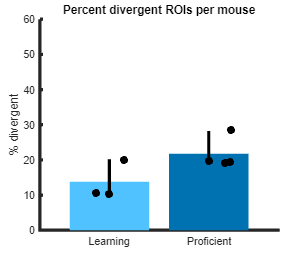

%Loading data
if exist('Figure2_ProcessedData.nwb', 'file') == 2
    Figure2_data = nwbRead("Figure2_ProcessedData.nwb",'ignorecache');
else
    qanswer = questdlg('Please select the location of Figure2_ProcessedData.nwb', ...
        'Choose file location', ...
        'Select','Exit','Select');
    switch qanswer
        case 'Select'
            [fname, fpath, eew] = uigetfile('*.nwb');
            fullpathtofile = strcat(fpath,fname);
            Figure2_data = nwbRead(fullpathtofile,'ignorecache');
        case 'Exit'
            return
    end
end

fn2 = 128; %number of processed sessions
for ct = 1:fn2
    if ct < 10
        name_file = append("file_0",num2str(ct));
    else
        name_file = append("file_",num2str(ct));
    end

    tempOdor = Figure2_data.processing.get('odor_Values').dynamictable.get('ProcessVar').getRow(ct); %172X1
    FigTwo.odor.(name_file).odor = tempOdor.odor{:,:};
    clear tempOdor
    tempOdor = Figure2_data.processing.get('odor_SM_Values').dynamictable.get('ProcessVar').getRow(ct); %172X1
    FigTwo.odor.(name_file).odor_SM = tempOdor.odor_SM{:,:};
    clear tempOdor
    tempOdor = Figure2_data.processing.get('odor_SP_Values').dynamictable.get('ProcessVar').getRow(ct); %172X1
    FigTwo.odor.(name_file).odor_SP = tempOdor.odor_SP{:,:};
    clear tempOdor
end
FigTwo.ROI.file2 = Figure2_data.processing.get('ROIfile2Values').dynamictable.get('ProcessVar').vectordata.get('roi_file2').data.load;
FigTwo.ROI.file6 = Figure2_data.processing.get('ROIfile6Values').dynamictable.get('ProcessVar').vectordata.get('roi_file6').data.load;
FigTwo.Time.timearray = Figure2_data.processing.get('TimeSpanValues').dynamictable.get('ProcessVar').vectordata.get('time_span').data.load';
FigTwo.DivergentResponse_data.all_cr = Figure2_data.processing.get('All_cr_Values').dynamictable.get('ProcessVar').vectordata.get('all_cr').data.load;
FigTwo.DivergentResponse_data.all_fa = Figure2_data.processing.get('All_fa_Values').dynamictable.get('ProcessVar').vectordata.get('all_fa').data.load;
FigTwo.DivergentResponse_data.all_hit = Figure2_data.processing.get('All_hit_Values').dynamictable.get('ProcessVar').vectordata.get('all_hit').data.load;
FigTwo.DivergentResponse_data.all_miss = Figure2_data.processing.get('All_miss_Values').dynamictable.get('ProcessVar').vectordata.get('all_miss').data.load;
FigTwo.DivergentResponse_data.dff_hit = Figure2_data.processing.get('Dff_hit_Values').dynamictable.get('ProcessVar').vectordata.get('dff_hit').data.load;
FigTwo.DivergentResponse_data.dff_miss = Figure2_data.processing.get('Dff_miss_Values').dynamictable.get('ProcessVar').vectordata.get('dff_miss').data.load;
FigTwo.DivergentResponse_data.dff_cr = Figure2_data.processing.get('Dff_cr_Values').dynamictable.get('ProcessVar').vectordata.get('dff_cr').data.load;
FigTwo.DivergentResponse_data.dff_fa = Figure2_data.processing.get('Dff_fa_Values').dynamictable.get('ProcessVar').vectordata.get('dff_fa').data.load;
FigTwo.DivergentResponse_data.delta_sminus = Figure2_data.processing.get('Delta_sminus_Values').dynamictable.get('ProcessVar').vectordata.get('delta_sminus').data.load';
FigTwo.DivergentResponse_data.delta_splus = Figure2_data.processing.get('Delta_splus_Values').dynamictable.get('ProcessVar').vectordata.get('delta_splus').data.load';
FigTwo.DivergentResponse_data.t = Figure2_data.processing.get('Div_t_Values').dynamictable.get('ProcessVar').vectordata.get('div_t').data.load';
FigTwo.DivergentResponse_data.spm = Figure2_data.processing.get('Spm_Values').dynamictable.get('ProcessVar').vectordata.get('spm').data.load;
FigTwo.DivergentResponse_data.spm_pcorr = Figure2_data.processing.get('Spm_pcorr_Values').dynamictable.get('ProcessVar').vectordata.get('spmpcorr').data.load';
FigTwo.DivergentResponse_data.sminus = Figure2_data.processing.get('Sminus_Values').dynamictable.get('ProcessVar').vectordata.get('sminus').data.load';
FigTwo.DivergentResponse_data.splus = Figure2_data.processing.get('Splus_Values').dynamictable.get('ProcessVar').vectordata.get('splus').data.load';
FigTwo.PercentCorrect.data = Figure2_data.processing.get('PerCorrValues').dynamictable.get('ProcessVar').vectordata.get('perCorr').data.load';
FigTwo.MouseUsed.data = Figure2_data.processing.get('MouseNoValues').dynamictable.get('ProcessVar').vectordata.get('mouse_No').data.load';
FigTwo.TrialAmt.data = Figure2_data.processing.get('TotalTrialValues').dynamictable.get('ProcessVar').vectordata.get('total_trials').data.load;

%only need these for the figures
delta_odor=4.127634e+00;
delta_odor_on_reinf_on=4.415787e+00;
delta_reinf=4.078266e-01;


% Time events of interest (e.g. stimulus onset/offset, cues etc.)
% They are marked on the plots with vertical lines
timeEvents = [0 delta_odor delta_odor_on_reinf_on delta_reinf+delta_odor_on_reinf_on];
% firingRates = folderOutput.second;
% time_span = folderOutput.timedata;
time_span = FigTwo.Time.timearray;
chosen = [36 38 29];
for ii = 1:3
    ii_p = chosen(ii);
    if ii == 1
        firingRates = FigTwo.ROI.file2;
        lastfile = 11;
    else
        firingRates = FigTwo.ROI.file6;
        lastfile = 15;
    end
    %     subplot(1,3,ii)
    figure()
    ax=gca;
    ax.LineWidth=3;
    min_ii=ii_p;

    %get the dF/F
    dFFsplus=zeros(length(time_span),lastfile); %constand value 11 for trialNum or 15 for 6
    dFFsplus(:,:)=firingRates(min_ii,1,:,1:lastfile);
    dFFsminus=zeros(length(time_span),lastfile);
    dFFsminus(:,:)=firingRates(min_ii,2,:,1:lastfile);

    sig_p=0;



    %S-
    if size(dFFsminus,2)>=3
        CIpvsm = bootci(1000, @mean, dFFsminus');
    else
        CIpvsm =zeros(2,size(dFFsminus,1));
    end
    meanpvsm=mean(dFFsminus,2)';
    CIpvsm(1,:)=meanpvsm-CIpvsm(1,:);
    CIpvsm(2,:)=CIpvsm(2,:)-meanpvsm;

    %S+
    if size(dFFsplus,2)>=3
        CIpvsp = bootci(1000, @mean, dFFsplus');
    else
        CIpvsp =zeros(2,size(dFFsplus,1));
    end
    meanpvsp=mean(dFFsplus,2)';
    CIpvsp(1,:)=meanpvsp-CIpvsp(1,:);
    CIpvsp(2,:)=CIpvsp(2,:)-meanpvsp;



    hold on


    %Do bounded lines
    [~, ~] = boundedline(time_span,mean(dFFsminus,2)', CIpvsm','cmap',[158/255 31/255 99/255]);

    [~, ~] = boundedline(time_span, mean(dFFsplus,2)', CIpvsp','cmap',[0 114/255 178/255]);



    %Now let's try and tile the single trials
    dFFupper=1.2*max([max(CIpvsm(:)) max(CIpvsp(:))]);
    no_traces=(size(dFFsminus,2)+size(dFFsplus,2)+2);
    deltadFF=dFFupper/no_traces;

    ii_trace=0;
    for trNo=1:size(dFFsminus,2)
        plot(time_span',(dFFsminus(:,trNo)'/no_traces)+ii_trace*deltadFF,'Color',[208/255 81/255 129/255],'LineWidth',0.5);
        ii_trace=ii_trace+1;
    end

    ii_trace=ii_trace+1;

    for trNo=1:size(dFFsplus,2)
        plot(time_span',(dFFsplus(:,trNo)'/no_traces)+ii_trace*deltadFF','Color',[0 164/255 228/255],'LineWidth',0.5);
        ii_trace=ii_trace+1;
    end

    %Plot the mean again
    plot(time_span',mean(dFFsminus,2),'Color',[178/255 51/255 119/255],'LineWidth',2);
    plot(time_span',mean(dFFsplus,2),'Color',[0 134/255 198/255],'LineWidth',2);

    this_ylim=ylim;
    for ii_te=1:length(timeEvents)
        plot([timeEvents(ii_te) timeEvents(ii_te)],this_ylim,'-k')
    end
    xlim([-7 15])

    xlabel('Time(sec)')
    ylabel('dFF')
end

%figure 2B-I


per_names{2}='40-65';
per_names{3}='65-80';
per_names{4}='>=80';

naive_pro{1}='Learning';
naive_pro{3}='Proficient';

peak_ii_legends{1}='cluster 1';
peak_ii_legends{2}='cluster 2';

delta_odor=4.127634e+00;
delta_odor_on_reinf_on=4.415787e+00;
delta_reinf=4.078266e-01;

% Time events of interest (e.g. stimulus onset/offset, cues etc.)
% They are marked on the plots with vertical lines
timeEvents = [-1.5 0 delta_odor delta_odor_on_reinf_on delta_reinf+delta_odor_on_reinf_on];

%Pairing of clusters
cluster_pairing.group(1).clus(1)=2;
cluster_pairing.group(1).clus(2)=1;
cluster_pairing.group(3).clus(1)=1;
cluster_pairing.group(3).clus(2)=2;

cluster_color{1}='m';
cluster_color{2}='b';
cluster_color{3}='y';
cluster_color{4}='r';
cluster_color{5}='c';
cluster_color{6}='g';

clus_per_peak_ii=[1 2];
time_window_clus=[1 1.2];

groups=[1 3];

%
%Time tinterval for shifting time base due to slow olfactometer computer
figureNo=0;
%
%Find out which files were included (>=min_tr trials)
files_included_glm = ones(1,length(FigTwo.TrialAmt.data)) == false;
files_included_glm(FigTwo.TrialAmt.data >= 12) = true;
%
figureNo = figureNo + 1;
try
    close(figureNo)
catch
end
hFig=figure(figureNo);
ax = gca;ax.LineWidth=3;
set(hFig, 'units','normalized','position',[.2 .2 .2 .3])
hold on
bar_offset=0;
edges= 0:10:80;
rand_offset=0.5;
%
total_ROIs_per_group_per_mouse=zeros(max(groups),max((FigTwo.MouseUsed.data)));
for grNo=groups
    these_odor=[];
    switch grNo
        case 1
            ROIs_included=(FigTwo.PercentCorrect.data >= 45) & (FigTwo.PercentCorrect.data <= 65);
        case 3
            ROIs_included=(FigTwo.PercentCorrect.data >= 80);
    end
    for mouseNo=unique(FigTwo.MouseUsed.data)
        switch grNo
            case 1
                files_included = (FigTwo.PercentCorrect.data >= 45) & (FigTwo.PercentCorrect.data <= 65) & (FigTwo.MouseUsed.data == mouseNo) & files_included_glm;
            case 3
                files_included = (FigTwo.PercentCorrect.data >= 80) & (FigTwo.MouseUsed.data == mouseNo) & files_included_glm;
        end
        these_per_div = [];
        for fileNo = 1:length(files_included)
            if fileNo < 10
                name_file = append("file_0",num2str(fileNo));
            else
                name_file = append("file_",num2str(fileNo));
            end
            if files_included(fileNo) == 1
                this_per_div = 100*sum(FigTwo.odor.(name_file).odor)/length(FigTwo.odor.(name_file).odor);
                these_per_div = [these_per_div this_per_div]; %#ok<AGROW>
                total_ROIs_per_group_per_mouse(grNo,mouseNo) = total_ROIs_per_group_per_mouse(grNo,mouseNo)+sum(FigTwo.odor.(name_file).odor);
            end
        end
        if ~isempty(these_per_div)
            these_odor = [these_odor mean(these_per_div)]; %#ok<AGROW>
        end
    end
    if ~isempty(these_odor)
        %             bar_offset=bar_offset+1;
        if grNo == 1
            bar(bar_offset,mean(these_odor),'LineWidth', 3,'EdgeColor','none','FaceColor',[80/255 194/255 255/255])
        else
            bar(bar_offset,mean(these_odor),'LineWidth', 3,'EdgeColor','none','FaceColor',[0 114/255 178/255])
        end
        if length(these_odor)>2
            %Violin plot [mean_out, CIout] =
            drgViolinPoint(these_odor...
                ,edges,bar_offset,rand_offset,'k','k',7);
        end
    end
    bar_offset=bar_offset+1;
end
%
xticks([0 1 2])
labels = 'xticklabels({''Learning'', ''Proficient''})';
labels=[labels(1:end-2) '})'];
eval(labels)
xlim([-0.7 1.7])
ylim([0 60])
ylabel('% divergent')
title('Percent divergent ROIs per mouse')

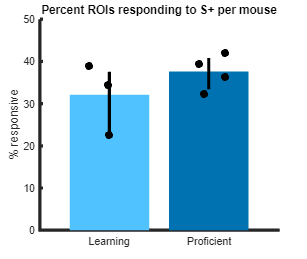

%
%Find out which files were included (>=10 trials)
files_included_glm = ones(1,length(FigTwo.TrialAmt.data)) == false;
files_included_glm(FigTwo.TrialAmt.data >= 6) = true;

%
figureNo = figureNo + 1;
try
    close(figureNo)
catch
end
hFig=figure(figureNo);
ax = gca;ax.LineWidth=3;
set(hFig, 'units','normalized','position',[.2 .2 .2 .3])
hold on
xticks([0 1 2])
bar_offset = 0;
%
for grNo=groups
    these_odor=[];
    for mouseNo=unique(FigTwo.MouseUsed.data)
        switch grNo
            case 1
                files_included=(FigTwo.PercentCorrect.data>=45) & (FigTwo.PercentCorrect.data<=65) & (FigTwo.MouseUsed.data==mouseNo) & files_included_glm;
            case 3
                files_included=(FigTwo.PercentCorrect.data>=80) & (FigTwo.MouseUsed.data==mouseNo) & files_included_glm;
        end
        these_per_resp=[];
        for fileNo=1:length(files_included)
            if fileNo < 10
                name_file = append("file_0",num2str(fileNo));
            else
                name_file = append("file_",num2str(fileNo));
            end
            if files_included(fileNo) == 1
                this_per_resp = 100*sum(FigTwo.odor.(name_file).odor_SP)/length(FigTwo.odor.(name_file).odor_SP);
                these_per_resp = [these_per_resp this_per_resp]; %#ok<AGROW>
            end
        end
        if ~isempty(these_per_resp)
            these_odor = [these_odor mean(these_per_resp)]; %#ok<AGROW>
        end
    end
    if ~isempty(these_odor)
        if grNo == 1
            bar(bar_offset,mean(these_odor),'LineWidth', 3,'EdgeColor','none','FaceColor',[80/255 194/255 255/255])
        else
            bar(bar_offset,mean(these_odor),'LineWidth', 3,'EdgeColor','none','FaceColor',[0 114/255 178/255])
        end
        if length(these_odor)>2
            %Violin plot
            drgViolinPoint(these_odor...
                ,edges,bar_offset,rand_offset,'k','k',7);
        end
    end
    bar_offset=bar_offset+1;
end
%
xticks([0 1 2])
labels = 'xticklabels({''Learning'', ''Proficient''})';
labels=[labels(1:end-2) '})'];
eval(labels)
xlim([-0.7 1.7])
ylim([0 50])
ylabel('% responsive')
title('Percent ROIs responding to S+ per mouse')

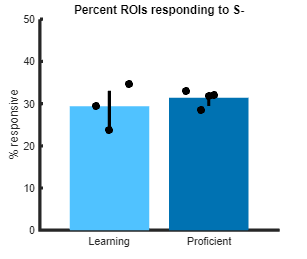

%
%Find out which files were included (>=10 trials)
files_included_glm = ones(1,length(FigTwo.TrialAmt.data)) == false;
files_included_glm(FigTwo.TrialAmt.data >= 6) = true;
%
figureNo = figureNo + 1;
try
    close(figureNo)
catch
end
hFig=figure(figureNo);
ax=gca;ax.LineWidth=3;
set(hFig, 'units','normalized','position',[.2 .2 .2 .3])
hold on
xticks([0 1 2])
bar_offset=0;
%
for grNo=groups
    these_odor=[];
    for mouseNo = unique(FigTwo.MouseUsed.data)
        switch grNo
            case 1
                files_included=(FigTwo.PercentCorrect.data >= 45)&(FigTwo.PercentCorrect.data <= 65)&(FigTwo.MouseUsed.data == mouseNo)&files_included_glm;
            case 3
                files_included=(FigTwo.PercentCorrect.data >= 80)&(FigTwo.MouseUsed.data == mouseNo)&files_included_glm;
        end
        if sum(files_included)>0
            these_per_resp = [];
            for fileNo=1:length(files_included)
                if files_included(fileNo) == 1
                    if fileNo < 10
                        name_file = append("file_0",num2str(fileNo));
                    else
                        name_file = append("file_",num2str(fileNo));
                    end
                    this_per_resp = 100*sum( FigTwo.odor.(name_file).odor_SM)/length(FigTwo.odor.(name_file).odor_SM);
                    these_per_resp = [these_per_resp this_per_resp]; %#ok<AGROW>
                end
            end
            if ~isempty(these_per_resp)
                these_odor = [these_odor mean(these_per_resp)]; %#ok<AGROW>
            end
        end

    end
    if grNo==1
        bar(bar_offset,mean(these_odor),'LineWidth', 3,'EdgeColor','none','FaceColor',[80/255 194/255 255/255])
    else
        bar(bar_offset,mean(these_odor),'LineWidth', 3,'EdgeColor','none','FaceColor',[0 114/255 178/255])
    end
    if length(these_odor)>2
        %Violin plot
        drgViolinPoint(these_odor...
            ,edges,bar_offset,rand_offset,'k','k',7);
    end
    bar_offset=bar_offset+1;
end
%
xticks([0 1 2])
labels = 'xticklabels({''Learning'', ''Proficient''})';
labels=[labels(1:end-2) '})'];
eval(labels)
xlim([-0.7 1.7])
ylim([0 50])
ylabel('% responsive')
title('Percent ROIs responding to S-')

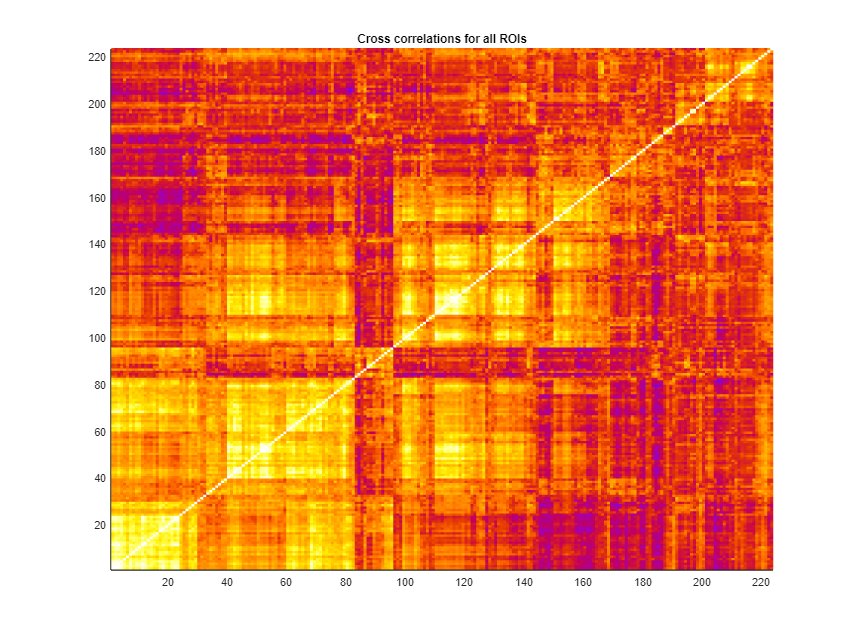

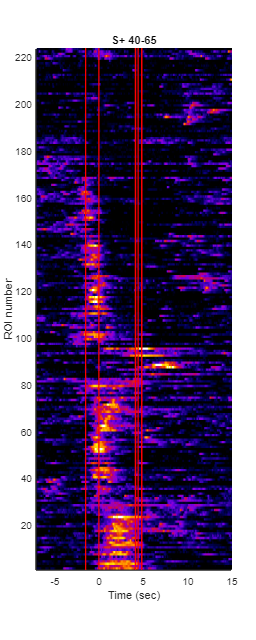

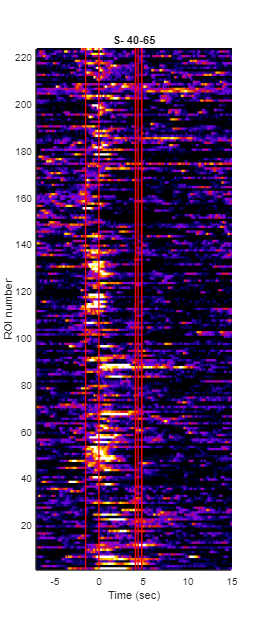

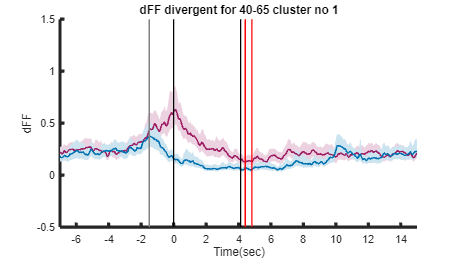

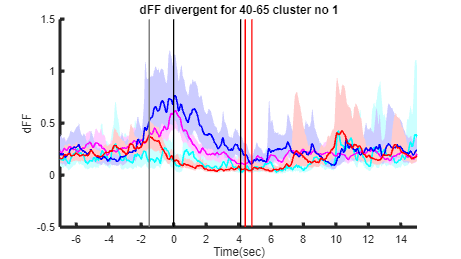

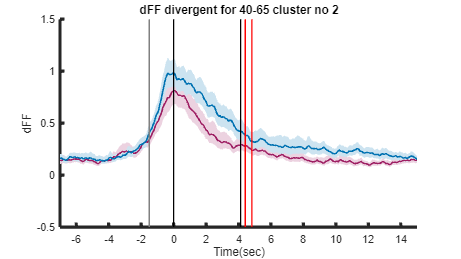

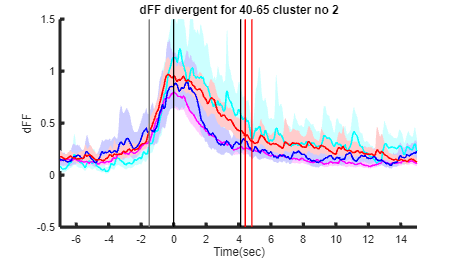

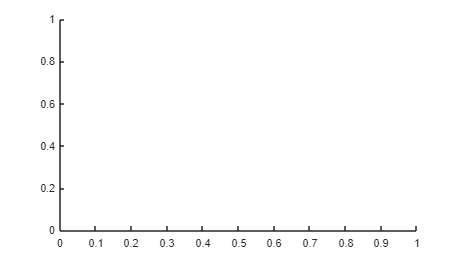

%
%Now plot the timecourses per group
divergence_times_per_group=[];
dFF_timecourse_per_clus=[];
for grNo=[1 3]
    switch grNo
        case 1
            ROIs_included = (FigTwo.DivergentResponse_data.spm_pcorr >= 45) & (FigTwo.DivergentResponse_data.spm_pcorr <= 65);
        case 3
            ROIs_included = (FigTwo.DivergentResponse_data.spm_pcorr >= 80);
    end
    if sum(ROIs_included)>0
        these_all_div_dFFsplus = zeros(size(FigTwo.DivergentResponse_data.splus,1),sum(ROIs_included));
        these_all_div_dFFsplus(:,:) = FigTwo.DivergentResponse_data.splus(:,logical(ROIs_included));

        these_all_div_dFFsminus = zeros(size(FigTwo.DivergentResponse_data.sminus,1),sum(ROIs_included));
        these_all_div_dFFsminus(:,:) = FigTwo.DivergentResponse_data.sminus(:,logical(ROIs_included));

        these_all_delta_dFFsplus = zeros(1,sum(ROIs_included));
        these_all_delta_dFFsplus(1,:) = FigTwo.DivergentResponse_data.delta_splus(1,logical(ROIs_included));

        these_all_delta_dFFsminus = zeros(1,sum(ROIs_included));
        these_all_delta_dFFsminus(1,:) = FigTwo.DivergentResponse_data.delta_sminus(1,logical(ROIs_included));

        these_all_div_t=zeros(1,sum(ROIs_included));
        these_all_div_t(1,:)= FigTwo.DivergentResponse_data.t(1,logical(ROIs_included));

        these_all_div_dFFhit = zeros(size(FigTwo.DivergentResponse_data.dff_hit,2),sum(ROIs_included));
        these_all_div_dFFhit(:,:) = FigTwo.DivergentResponse_data.dff_hit(logical(ROIs_included),:)';

        these_all_hit = zeros(sum(ROIs_included),1);
        these_all_hit(:,1) = FigTwo.DivergentResponse_data.all_hit(logical(ROIs_included));
        %             these_all_hit(:,:)=FigTwo.DivergentResponse_data.all_hit(1,logical(ROIs_included))';

        these_all_div_dFFmiss = zeros(size(FigTwo.DivergentResponse_data.dff_miss,2),sum(ROIs_included));
        these_all_div_dFFmiss(:,:) = FigTwo.DivergentResponse_data.dff_miss(logical(ROIs_included),:)';

        these_all_miss = zeros(sum(ROIs_included),1);
        these_all_miss(:,1) = FigTwo.DivergentResponse_data.all_miss(logical(ROIs_included));
        %             these_all_miss(:,:) = FigTwo.DivergentResponse_data.all_miss(1,logical(ROIs_included))';

        these_all_div_dFFcr = zeros(size(FigTwo.DivergentResponse_data.dff_cr,2),sum(ROIs_included));
        these_all_div_dFFcr(:,:) = FigTwo.DivergentResponse_data.dff_cr(logical(ROIs_included),:)';

        these_all_cr = zeros(sum(ROIs_included),1);
        these_all_cr(:,1) = FigTwo.DivergentResponse_data.all_cr(logical(ROIs_included));
        %             these_all_cr(:,:)=FigTwo.DivergentResponse_data.all_cr(1,logical(ROIs_included))';

        these_all_div_dFFfa = zeros(size(FigTwo.DivergentResponse_data.dff_fa,2),sum(ROIs_included));
        these_all_div_dFFfa(:,:) = FigTwo.DivergentResponse_data.dff_fa(logical(ROIs_included),:)';

        these_all_fa = zeros(sum(ROIs_included),1);
        these_all_fa(:,1) = FigTwo.DivergentResponse_data.all_fa(logical(ROIs_included));


        %             croscorr_traces=corrcoef(these_all_div_dFFspm);
        croscorr_traces=corrcoef(these_all_div_dFFsplus);

        Z = linkage(croscorr_traces,'complete','correlation');

        clusters = cluster(Z,'Maxclust',2);
        figureNo=figureNo+1;
        try
            close(figureNo)
        catch
        end

        hFig = figure(figureNo); %#ok
        cutoff = median([Z(end-1,3) Z(end,3)]);
        [H,~,outperm]=dendrogram(Z,0,'Orientation','left','ColorThreshold',cutoff);
        H_output = H;
        set(H,'LineWidth',2)
        if grNo == 3
            set(H,'LineWidth',2)
            hFig=figure(figureNo);
            set(hFig, 'units','normalized','position',[.05 .1 .14 .8])
        else
            close(figureNo);
            figureNo = figureNo-1;
        end

        %re-sort the matrix
        perm_croscorr_traces = nan([size(croscorr_traces,1),size(croscorr_traces,1)]);
        for ii=1:size(croscorr_traces,1)
            for jj=1:size(croscorr_traces,1)
                perm_croscorr_traces(ii,jj) = croscorr_traces(outperm(ii),outperm(jj));
            end
        end

        figureNo=figureNo+1;
        try
            close(figureNo)
        catch
        end

        hFig = figure(figureNo);

        set(hFig, 'units','normalized','position',[.15 .1 .6 .8])
        hold on
        %
        pcolor(perm_croscorr_traces)
        %
        colormap fire
        shading flat
        clim([-1  1])
        title('Cross correlations for all ROIs')
        xlim([1 sum(ROIs_included)])
        ylim([1 sum(ROIs_included)])
        %
        %S+
        figureNo=figureNo+1;
        try
            close(figureNo)
        catch
        end
        hFig = figure(figureNo);
        set(hFig, 'units','normalized','position',[.05 .1 .18 .8])
        hold on
        %
        sorted_handles_out.all_div_dFFsplus=[];
        sorted_handles_out.all_div_dFFsplus=these_all_div_dFFsplus(:,outperm)';
        ii_included=size(sorted_handles_out.all_div_dFFsplus,1);
        time_span_mat=repmat(FigTwo.Time.timearray,ii_included,1);
        ROI_mat=repmat(1:ii_included,length(FigTwo.Time.timearray),1)';
        %
        pcolor(time_span_mat,ROI_mat,sorted_handles_out.all_div_dFFsplus)
        %
        colormap fire
        shading flat
        clim([prctile(FigTwo.DivergentResponse_data.spm(:),1) prctile(FigTwo.DivergentResponse_data.spm(:),99.9)])
        %
        for ii_te=1:length(timeEvents)
            plot([timeEvents(ii_te) timeEvents(ii_te)],[0 2400],'-r')
        end
        %
        xlim([-7 15])
        ylim([1 ii_included])
        title(['S+ ' per_names{grNo+1}])
        xlabel('Time (sec)')
        ylabel('ROI number')
        %
        %S-
        figureNo=figureNo+1;
        try
            close(figureNo)
        catch
        end
        hFig = figure(figureNo);
        set(hFig, 'units','normalized','position',[.05 .1 .18 .8])
        hold on
        %
        sorted_handles_out.all_div_dFFsminus=[];
        sorted_handles_out.all_div_dFFsminus=these_all_div_dFFsminus(:,outperm)';
        ii_included=size(sorted_handles_out.all_div_dFFsplus,1);
        time_span_mat=repmat(FigTwo.Time.timearray,ii_included,1);
        ROI_mat=repmat(1:ii_included,length(FigTwo.Time.timearray),1)';
        %
        pcolor(time_span_mat,ROI_mat,sorted_handles_out.all_div_dFFsminus)
        %
        colormap fire
        shading flat
        clim([prctile(FigTwo.DivergentResponse_data.spm(:),1) prctile(FigTwo.DivergentResponse_data.spm(:),99)])
        %
        for ii_te=1:length(timeEvents)
            plot([timeEvents(ii_te) timeEvents(ii_te)],[0 2400],'-r')
        end
        %
        xlim([-7 15])
        ylim([1 ii_included])
        title(['S- ' per_names{grNo+1}])
        xlabel('Time (sec)')
        ylabel('ROI number')
        %
        %Plot the average timecourses per cluster
        for clus=1:max(clusters)
            %Plot the average of this cluster for S+ and S-
            figureNo = figureNo + 1;
            try
                close(figureNo)
            catch
            end
            hFig=figure(figureNo);
            ax=gca;ax.LineWidth=3;
            set(hFig, 'units','normalized','position',[.3 .2 .3 .3])
            hold on
            %
            %get the dF/F
            %S-
            include_total = clusters == clus;
            this_cluster_dFFsminus= nan([sum(include_total),size(these_all_div_dFFsminus,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFsminus,2)
                if clusters(ii)==clus
                    ii_included=ii_included+1;
                    this_cluster_dFFsminus(ii_included,:) = these_all_div_dFFsminus(:,ii)';
                end
            end

            dFF_timecourse_per_clus.group(grNo).cluster(clus).sminus_timecourses=this_cluster_dFFsminus;

            CIpv = bootci(1000, @mean, this_cluster_dFFsminus);
            meanpv=mean(this_cluster_dFFsminus,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;
            %
            boundedline(FigTwo.Time.timearray,mean(this_cluster_dFFsminus), CIpv','cmap',[158/255 31/255 99/255]);

            %S+
            this_cluster_dFFsplus= nan([sum(include_total),size(these_all_div_dFFsplus,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFsplus,2)
                if clusters(ii)==clus
                    ii_included=ii_included+1;
                    this_cluster_dFFsplus(ii_included,:) = these_all_div_dFFsplus(:,ii)';
                end
            end

            dFF_timecourse_per_clus.group(grNo).cluster(clus).splus_timecourses=this_cluster_dFFsplus;

            CIpv = bootci(1000, @mean, this_cluster_dFFsplus);
            meanpv=mean(this_cluster_dFFsplus,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;

            boundedline(FigTwo.Time.timearray, mean(this_cluster_dFFsplus), CIpv','cmap',[0 114/255 178/255]);
            plot(FigTwo.Time.timearray',mean(this_cluster_dFFsminus)','Color',[158/255 31/255 99/255],'LineWidth',1.5);
            plot(FigTwo.Time.timearray',mean(this_cluster_dFFsplus)','Color',[0 114/255 178/255],'LineWidth',1.5);
            %
            ylim([-0.5 1.5])
            xlim([-7 15])
            this_ylim = ylim;

            %FV
            plot([-1.5 -1.5],this_ylim,'-','Color',[0.5 0.5 0.5])

            %Odor on markers
            plot([0 0],this_ylim,'-k')
            plot([mean(delta_odor) mean(delta_odor)],this_ylim,'-k')

            %Reinforcement markers
            plot([mean(delta_odor_on_reinf_on) mean(delta_odor_on_reinf_on)],this_ylim,'-r')
            plot([mean(delta_odor_on_reinf_on+delta_reinf) mean(delta_odor_on_reinf_on+delta_reinf)],this_ylim,'-r')
            xlabel('Time(sec)')
            ylabel('dFF')
            title(['dFF divergent for ' per_names{grNo+1} ' cluster no ' num2str(clus)])
            %
            %Plot the average of this cluster for hit, miss cr and fa
            figureNo = figureNo + 1;
            try
                close(figureNo)
            catch
            end
            hFig=figure(figureNo);
            ax=gca;ax.LineWidth=3;
            set(hFig, 'units','normalized','position',[.3 .2 .3 .3]);
            hold on
            %get the dF/F
            %miss
            include_total = (clusters == clus) & (these_all_miss == 1);
            this_cluster_dFFmiss = nan([sum(include_total),size(these_all_div_dFFmiss,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFmiss,2)
                if (clusters(ii)==clus) && (these_all_miss(ii)==1)
                    ii_included=ii_included+1;
                    this_cluster_dFFmiss(ii_included,:) = these_all_div_dFFmiss(:,ii)';
                end
            end

            dFF_timecourse_per_clus.group(grNo).cluster(clus).miss_timecourses=this_cluster_dFFmiss;


            CIpv = bootci(1000, @mean, this_cluster_dFFmiss);
            meanpv=mean(this_cluster_dFFmiss,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;

            boundedline(FigTwo.Time.timearray,mean(this_cluster_dFFmiss), CIpv','c');

            %fa
            include_total = (clusters == clus) & (these_all_fa == 1);
            this_cluster_dFFfa = nan([sum(include_total),size(these_all_div_dFFfa,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFfa,2)
                if (clusters(ii)==clus) && (these_all_fa(ii)==1)
                    ii_included=ii_included+1;
                    this_cluster_dFFfa(ii_included,:)=these_all_div_dFFfa(:,ii)';
                end
            end

            dFF_timecourse_per_clus.group(grNo).cluster(clus).fa_timecourses=this_cluster_dFFfa;


            CIpv = bootci(1000, @mean, this_cluster_dFFfa);
            meanpv=mean(this_cluster_dFFfa,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;

            boundedline(FigTwo.Time.timearray,mean(this_cluster_dFFfa), CIpv','m');

            %cr
            include_total = (clusters == clus) & (these_all_cr == 1);
            this_cluster_dFFcr = nan([sum(include_total),size(these_all_div_dFFcr,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFcr,2)
                if (clusters(ii)==clus) && (these_all_cr(ii)==1)
                    ii_included=ii_included+1;
                    this_cluster_dFFcr(ii_included,:)=these_all_div_dFFcr(:,ii)';
                end
            end

            dFF_timecourse_per_clus.group(grNo).cluster(clus).cr_timecourses=this_cluster_dFFcr;


            CIpv = bootci(1000, @mean, this_cluster_dFFcr);
            meanpv=mean(this_cluster_dFFcr,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;

            boundedline(FigTwo.Time.timearray,mean(this_cluster_dFFcr), CIpv','b');

            %hit
            include_total = (clusters == clus) & (these_all_hit == 1);
            this_cluster_dFFhit = nan([sum(include_total),size(these_all_div_dFFhit,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFhit,2)
                if (clusters(ii)==clus) && (these_all_hit(ii)==1)
                    ii_included=ii_included+1;
                    this_cluster_dFFhit(ii_included,:)=these_all_div_dFFhit(:,ii)';
                end
            end
            dFF_timecourse_per_clus.group(grNo).cluster(clus).hit_timecourses=this_cluster_dFFhit;
            CIpv = bootci(1000, @mean, this_cluster_dFFhit);
            meanpv=mean(this_cluster_dFFhit,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;
            %
            boundedline(FigTwo.Time.timearray,mean(this_cluster_dFFhit), CIpv','r');
            %
            plot(FigTwo.Time.timearray',mean(this_cluster_dFFmiss)','-c','LineWidth',1.5);
            plot(FigTwo.Time.timearray',mean(this_cluster_dFFfa)','-m','LineWidth',1.5);
            plot(FigTwo.Time.timearray',mean(this_cluster_dFFcr)','-b','LineWidth',1.5);
            plot(FigTwo.Time.timearray',mean(this_cluster_dFFhit)','-r','LineWidth',1.5);
            %
            ylim([-0.5 1.5])
            xlim([-7 15])
            this_ylim=ylim;
            %
            %FV
            plot([-1.5 -1.5],this_ylim,'-','Color',[0.5 0.5 0.5])
            %Odor on markers
            plot([0 0],this_ylim,'-k')
            plot([mean(delta_odor) mean(delta_odor)],this_ylim,'-k')

            %Reinforcement markers
            plot([mean(delta_odor_on_reinf_on) mean(delta_odor_on_reinf_on)],this_ylim,'-r')
            plot([mean(delta_odor_on_reinf_on+delta_reinf) mean(delta_odor_on_reinf_on+delta_reinf)],this_ylim,'-r')
            %
            xlabel('Time(sec)')
            ylabel('dFF')
            title(['dFF divergent for ' per_names{grNo+1} ' cluster no ' num2str(clus)])
            %
        end
        %
        figureNo=figureNo+1;
        try
            close(figureNo)
        catch
        end
        hFig = figure(figureNo);
        set(hFig, 'units','normalized','position',[.2 .2 .3 .3])
        hold on
        %Get the color for each cluster
        if grNo == 3
            linesColor = cell2mat(get(H,'Color')); % get lines color;
            colorList = unique(linesColor, 'rows');
            %
            X_color     = zeros(sum(ROIs_included),3);
            X_cluster   = zeros(sum(ROIs_included),1);
            for iLeaf = 1:sum(ROIs_included)
                [iRow, ~] = find(Z==iLeaf);
                color = linesColor(iRow,:); % !
                % assign color to each observation
                X_color(iLeaf,:) = color;
                % assign cluster number to each observation
                X_cluster(iLeaf,:) = find(ismember(colorList, color, 'rows'));
            end
            cluster_colors=zeros(max(clusters),3);
            for clus= 1:max(clusters)
                this_ii=find(clusters==clus,1,'first');
                cluster_colors(clus,:) = X_color(this_ii,:);
            end
            %             these_cluster_colors= cluster_colors;

            for clus=1:max(clusters)
                %S-
                %             this_cluster_delta_dFFsminus=[];
                include_total = (clusters == clus);
                this_cluster_delta_dFFsminus = nan([1,sum(include_total)]);
                ii_included=0;
                for ii=1:size(these_all_delta_dFFsminus,2)
                    if clusters(ii)==clus
                        ii_included=ii_included+1;
                        this_cluster_delta_dFFsminus(1,ii_included)=these_all_delta_dFFsminus(1,ii)';
                    end
                end
                %S+
                %             this_cluster_delta_dFFsplus=[];
                this_cluster_delta_dFFsplus = nan([1,sum(include_total)]);
                ii_included=0;
                for ii=1:size(these_all_delta_dFFsplus,2)
                    if clusters(ii)==clus
                        ii_included=ii_included+1;
                        this_cluster_delta_dFFsplus(1,ii_included)=these_all_delta_dFFsplus(1,ii)';
                    end
                end
                this_color=zeros(1,3);
                this_color(1,:)=cluster_colors(clus,:);
                plot(this_cluster_delta_dFFsminus,this_cluster_delta_dFFsplus,'.','Color',this_color)
            end
            %
            ylabel('Delta zdFF S+')
            xlabel('Delta zdFF S-')
            title(['Delta zdFF S+ vs S- for' per_names{grNo+1}])
            %
        end
        divergence_times_per_group.group(grNo).div_t=these_all_div_t;
    end
end

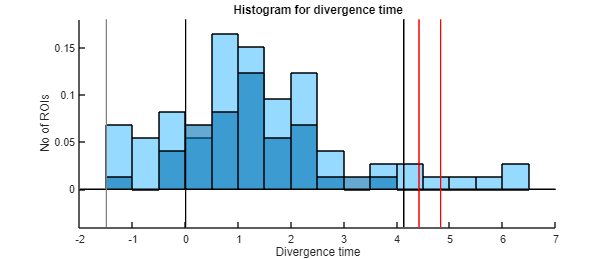

%Divergence time histogram
figureNo=figureNo+1;
try
    close(figureNo)
catch
end
hFig = figure(figureNo);
set(hFig, 'units','normalized','position',[.2 .2 .4 .3])
hold on
edges= -1.5:0.5:6.5 ;
%
histogram(divergence_times_per_group.group(1).div_t(divergence_times_per_group.group(1).div_t<=7)',edges,...
    'Normalization','probability','FaceColor',[80/255 194/255 255/255])
histogram(divergence_times_per_group.group(3).div_t(divergence_times_per_group.group(1).div_t<=7)',edges,...
    'Normalization','probability','FaceColor',[0 114/255 178/255])
%
plot([-3 7],[0 0],'-k')
xlim([-2 7])
ylim([-0.04 0.18])
%
this_ylim=ylim;
%FV
% fvhl=plot([-1.5 0],[this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1)) this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1))],'-'...
%     ,'Color',[0.9 0.9 0.9],'LineWidth',5);
plot([-1.5 -1.5],this_ylim,'-','Color',[0.5 0.5 0.5])
%Odor on markers
plot([0 0],this_ylim,'-k')
% odorhl=plot([0 mean(delta_odor)],[this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1)) this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1))],'-k','LineWidth',5);
plot([mean(delta_odor) mean(delta_odor)],this_ylim,'-k')
%Reinforcement markers
plot([mean(delta_odor_on_reinf_on) mean(delta_odor_on_reinf_on)],this_ylim,'-r')
% reinfhl=plot([mean(delta_odor_on_reinf_on) mean(delta_odor_on_reinf_on+delta_reinf)],[this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1)) this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1))],'-r','LineWidth',5);
plot([mean(delta_odor_on_reinf_on+delta_reinf) mean(delta_odor_on_reinf_on+delta_reinf)],this_ylim,'-r')
%
ylabel('No of ROIs')
xlabel('Divergence time')
title('Histogram for divergence time')

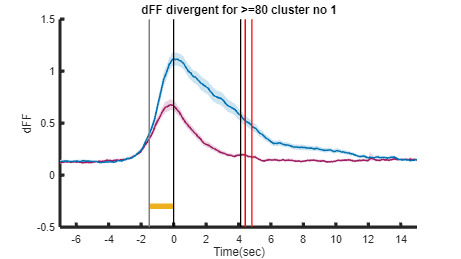

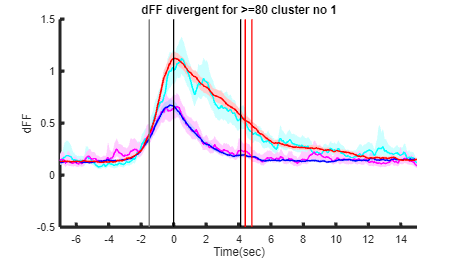

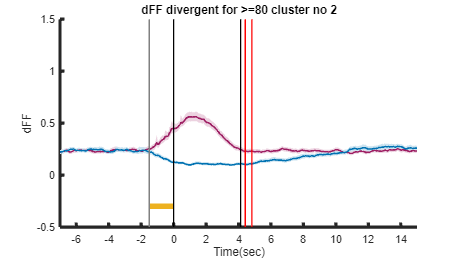

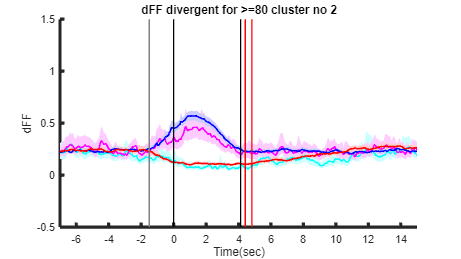


%
time_span = FigTwo.Time.timearray;
%Now plot the timecourses per group
divergence_times_per_group=[];
dFF_timecourse_per_clus=[];
for grNo= [1,3] %only need 3 not 1

    switch grNo
        case 1
            ROIs_included = (FigTwo.DivergentResponse_data.spm_pcorr >= 45) & (FigTwo.DivergentResponse_data.spm_pcorr <= 65);
        case 3
            ROIs_included = (FigTwo.DivergentResponse_data.spm_pcorr >= 80);
    end

    if sum(ROIs_included)>0

        %Calculate the crosscorrelations
        these_all_div_dFFspm = zeros(size(FigTwo.DivergentResponse_data.spm,1),sum(ROIs_included));
        these_all_div_dFFspm(:,:) = FigTwo.DivergentResponse_data.spm(:,logical(ROIs_included));

        croscorr_traces=corrcoef(these_all_div_dFFsplus);

        Z = linkage(croscorr_traces,'complete','correlation');
        clusters = cluster(Z,'Maxclust',2);
        if grNo == 3
            value_Z = Z;

        end
        %         %Plot the average timecourses per cluster
        for clus=1:max(clusters)
            %             %Plot the average of this cluster for S+ and S-
            if grNo == 3
                figureNo = figureNo + 1;
                try
                    close(figureNo)
                catch
                end
                hFig=figure(figureNo);
                ax=gca;ax.LineWidth=3;
                set(hFig, 'units','normalized','position',[.3 .2 .3 .3])
                hold on
            end
            %get the dF/F
            %S-
            include_total = clusters == clus;
            this_cluster_dFFsminus= nan([sum(include_total),size(these_all_div_dFFsminus,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFsminus,2)
                if clusters(ii) == clus
                    ii_included=ii_included+1;
                    this_cluster_dFFsminus(ii_included,:)=these_all_div_dFFsminus(:,ii)';
                end
            end

            dFF_timecourse_per_clus.group(grNo).cluster(clus).sminus_timecourses=this_cluster_dFFsminus;
            CIpv = bootci(1000, @mean, this_cluster_dFFsminus);
            meanpv=mean(this_cluster_dFFsminus,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;
            if grNo == 3
                boundedline(FigTwo.Time.timearray,mean(this_cluster_dFFsminus), CIpv','cmap',[158/255 31/255 99/255]);
            end
            %S+
            this_cluster_dFFsplus= nan([sum(include_total),size(these_all_div_dFFsplus,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFsplus,2)
                if clusters(ii)==clus
                    ii_included=ii_included+1;
                    this_cluster_dFFsplus(ii_included,:)=these_all_div_dFFsplus(:,ii)';
                end
            end
            dFF_timecourse_per_clus.group(grNo).cluster(clus).splus_timecourses=this_cluster_dFFsplus;
            CIpv = bootci(1000, @mean, this_cluster_dFFsplus);
            meanpv=mean(this_cluster_dFFsplus,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;
            %
            if grNo == 3
                boundedline(FigTwo.Time.timearray, mean(this_cluster_dFFsplus), CIpv','cmap',[0 114/255 178/255]);
                plot(FigTwo.Time.timearray',mean(this_cluster_dFFsminus)','Color',[158/255 31/255 99/255],'LineWidth',1.5);
                plot(FigTwo.Time.timearray',mean(this_cluster_dFFsplus)','Color',[0 114/255 178/255],'LineWidth',1.5);
                %end of figure 8 (do not need)
            end
            %
            if grNo == 3
                ylim([-0.5 1.5])
                xlim([-7 15])
                this_ylim=ylim;
                %FV fvhl=
                plot([-1.5 0],[this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1)) this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1))],'-'...
                    ,'MarkerEdgeColor',[0.9 0.9 0.9],'MarkerFaceColor',[0.9 0.9 0.9],'LineWidth',5);
                plot([-1.5 -1.5],this_ylim,'-','Color',[0.5 0.5 0.5])

                %Odor on markers
                plot([0 0],this_ylim,'-k')
                %                 odorhl=plot([0 mean(delta_odor)],[this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1)) this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1))],'-k','LineWidth',5);
                plot([mean(delta_odor) mean(delta_odor)],this_ylim,'-k')

                %Reinforcement markers
                plot([mean(delta_odor_on_reinf_on) mean(delta_odor_on_reinf_on)],this_ylim,'-r')
                %                 reinfhl=plot([mean(delta_odor_on_reinf_on) mean(delta_odor_on_reinf_on+delta_reinf)],[this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1)) this_ylim(1)+0.1*(this_ylim(2)-this_ylim(1))],'-r','LineWidth',5);
                plot([mean(delta_odor_on_reinf_on+delta_reinf) mean(delta_odor_on_reinf_on+delta_reinf)],this_ylim,'-r')
                xlabel('Time(sec)')
                ylabel('dFF')
                title(['dFF divergent for ' per_names{grNo+1} ' cluster no ' num2str(clus)])
                %Plot the average of this cluster for hit, miss cr and fa
                figureNo = figureNo + 1;
                try
                    close(figureNo)
                catch
                end
                hFig=figure(figureNo);

                ax=gca;ax.LineWidth=3;
                set(hFig, 'units','normalized','position',[.3 .2 .3 .3])


                hold on
            end
            %get the dF/F

            %miss
            %             this_cluster_dFFmiss=[];
            include_total = (clusters == clus) & (these_all_miss == 1);
            this_cluster_dFFmiss = nan([sum(include_total),size(these_all_div_dFFmiss,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFmiss,2)
                if (clusters(ii)==clus) && (these_all_miss(ii)==1)
                    ii_included=ii_included+1;
                    this_cluster_dFFmiss(ii_included,:)=these_all_div_dFFmiss(:,ii)';
                end
            end
            dFF_timecourse_per_clus.group(grNo).cluster(clus).miss_timecourses=this_cluster_dFFmiss;
            CIpv = bootci(1000, @mean, this_cluster_dFFmiss);
            meanpv=mean(this_cluster_dFFmiss,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;
            %
            if grNo == 3
                boundedline(FigTwo.Time.timearray,mean(this_cluster_dFFmiss), CIpv','c');
            end
            %
            %fa
            %             this_cluster_dFFfa=[];
            include_total = (clusters == clus) & (these_all_fa == 1);
            this_cluster_dFFfa = nan([sum(include_total),size(these_all_div_dFFfa,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFfa,2)
                if (clusters(ii)==clus) && (these_all_fa(ii)==1)
                    ii_included=ii_included+1;
                    this_cluster_dFFfa(ii_included,:)=these_all_div_dFFfa(:,ii)';
                end
            end
            dFF_timecourse_per_clus.group(grNo).cluster(clus).fa_timecourses=this_cluster_dFFfa;
            CIpv = bootci(1000, @mean, this_cluster_dFFfa);
            meanpv=mean(this_cluster_dFFfa,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;
            %
            if grNo == 3
                boundedline(FigTwo.Time.timearray,mean(this_cluster_dFFfa), CIpv','m');
            end
            %
            %cr
            %             this_cluster_dFFcr=[];
            include_total = (clusters == clus) & (these_all_cr == 1);
            this_cluster_dFFcr = nan([sum(include_total),size(these_all_div_dFFcr,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFcr,2)
                if (clusters(ii)==clus) && (these_all_cr(ii)==1)
                    ii_included=ii_included+1;
                    this_cluster_dFFcr(ii_included,:)=these_all_div_dFFcr(:,ii)';
                end
            end
            dFF_timecourse_per_clus.group(grNo).cluster(clus).cr_timecourses=this_cluster_dFFcr;
            CIpv = bootci(1000, @mean, this_cluster_dFFcr);
            meanpv=mean(this_cluster_dFFcr,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;
            %
            if grNo == 3
                boundedline(FigTwo.Time.timearray,mean(this_cluster_dFFcr), CIpv','b');
            end
            %
            %hit
            %             this_cluster_dFFhit=[];
            include_total = (clusters == clus) & (these_all_hit == 1);
            this_cluster_dFFhit = nan([sum(include_total),size(these_all_div_dFFhit,1)]);
            ii_included=0;
            for ii=1:size(these_all_div_dFFhit,2)
                if (clusters(ii)==clus) && (these_all_hit(ii)==1)
                    ii_included=ii_included+1;
                    this_cluster_dFFhit(ii_included,:)=these_all_div_dFFhit(:,ii)';
                end
            end

            dFF_timecourse_per_clus.group(grNo).cluster(clus).hit_timecourses=this_cluster_dFFhit;


            CIpv = bootci(1000, @mean, this_cluster_dFFhit);
            meanpv=mean(this_cluster_dFFhit,1);
            CIpv(1,:)=meanpv-CIpv(1,:);
            CIpv(2,:)=CIpv(2,:)-meanpv;
            if grNo == 3
                [hlpvl, hppvl] = boundedline(FigTwo.Time.timearray,mean(this_cluster_dFFhit), CIpv','r');


                plot(FigTwo.Time.timearray',mean(this_cluster_dFFmiss)','-c','LineWidth',1.5);
                plot(FigTwo.Time.timearray',mean(this_cluster_dFFfa)','-m','LineWidth',1.5);
                plot(FigTwo.Time.timearray',mean(this_cluster_dFFcr)','-b','LineWidth',1.5);
                plot(FigTwo.Time.timearray',mean(this_cluster_dFFhit)','-r','LineWidth',1.5);




                ylim([-0.5 1.5])
                xlim([-7 15])
                this_ylim=ylim;

                %FV
                plot([-1.5 -1.5],this_ylim,'-','Color',[0.5 0.5 0.5])

                %Odor on markers
                plot([0 0],this_ylim,'-k')
                plot([mean(delta_odor) mean(delta_odor)],this_ylim,'-k')

                %Reinforcement markers
                plot([mean(delta_odor_on_reinf_on) mean(delta_odor_on_reinf_on)],this_ylim,'-r')
                plot([mean(delta_odor_on_reinf_on+delta_reinf) mean(delta_odor_on_reinf_on+delta_reinf)],this_ylim,'-r')


                xlabel('Time(sec)')
                ylabel('dFF')


                title(['dFF divergent for ' per_names{grNo+1} ' cluster no ' num2str(clus)])
            end
        end

    end
end

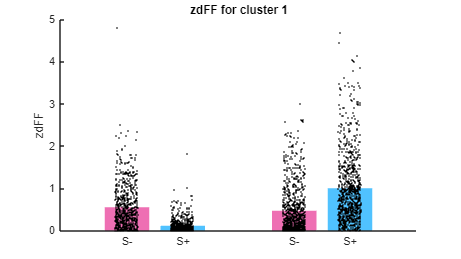

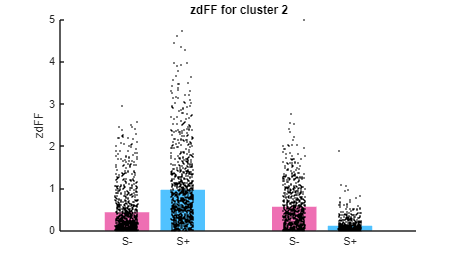


%plotting figure

figureNo=figureNo+1;
try
    close(figureNo)
catch
end

hFig = figure(figureNo);
cutoff = median([value_Z(end-1,3) value_Z(end,3)]);
[H,T,outperm]=dendrogram(value_Z,0,'Orientation','left','ColorThreshold',cutoff);
close(figureNo)
%
for peak_ii=1:length(clus_per_peak_ii)

    figureNo=figureNo+1;
    try
        close(figureNo)
    catch
    end

    hFig = figure(figureNo);

    set(hFig, 'units','normalized','position',[.2 .2 .3 .3])

    hold on

    clus=clus_per_peak_ii(peak_ii);

    this_time_window=[time_window_clus(peak_ii)-0.5 time_window_clus(peak_ii)+0.5];
    bar_offset=0;

    edges= -1:0.05:5 ;
    rand_offset=0.4;

    for grNo =[1 3]

        actual_clus=cluster_pairing.group(grNo).clus(clus);

        %do S-
        these_dFF_minus=mean(dFF_timecourse_per_clus.group(grNo).cluster(actual_clus).sminus_timecourses...
            (:,(FigTwo.Time.timearray>=this_time_window(1))&(FigTwo.Time.timearray<=this_time_window(2))),2);

        bar_offset=bar_offset+1;
        bar(bar_offset,mean(these_dFF_minus),'LineWidth', 3,'EdgeColor','none','FaceColor',[238/255 111/255 179/255])

        %Violin plot
        drgViolinPoint(these_dFF_minus...
            ,edges,bar_offset,rand_offset,'k','k',1);

        %do S+
        these_dFF_plus=mean(dFF_timecourse_per_clus.group(grNo).cluster(actual_clus).splus_timecourses...
            (:,(FigTwo.Time.timearray>=this_time_window(1))&(FigTwo.Time.timearray<=this_time_window(2))),2);

        bar_offset=bar_offset+1;
        bar(bar_offset,mean(these_dFF_plus),'LineWidth', 3,'EdgeColor','none','FaceColor',[80/255 194/255 255/255])

        %Violin plot
        drgViolinPoint(these_dFF_plus...
            ,edges,bar_offset,rand_offset,'k','k',1);

        bar_offset=bar_offset+1;
    end

    xticks([1 2 4 5])
    xticklabels({'S-','S+','S-','S+'})

    ylabel('zdFF')

    title(['zdFF for ' peak_ii_legends{peak_ii}])

end

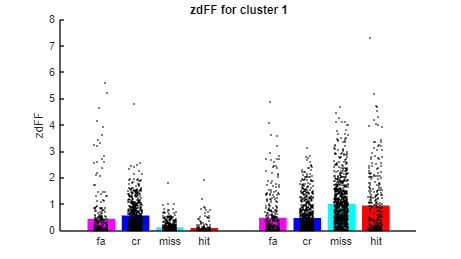

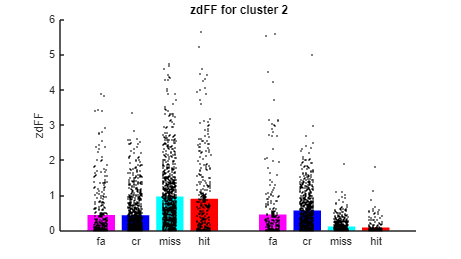

%figure I
for peak_ii=1:2

    %Plot bar graph for hit, miss, cr and fa

    figureNo=figureNo+1;
    try
        close(figureNo)
    catch
    end

    hFig = figure(figureNo);

    set(hFig, 'units','normalized','position',[.2 .2 .3 .3])

    hold on

    clus=clus_per_peak_ii(peak_ii);

    this_time_window=[time_window_clus(peak_ii)-0.5 time_window_clus(peak_ii)+0.5];

    bar_offset=0;

    edges= -1:0.05:5 ;
    rand_offset=0.4;
    for grNo =[1 3]
        actual_clus=cluster_pairing.group(grNo).clus(clus);
        %do fa
        these_dFF_fa=mean(dFF_timecourse_per_clus.group(grNo).cluster(actual_clus).fa_timecourses...
            (:,(FigTwo.Time.timearray>=this_time_window(1))&(FigTwo.Time.timearray<=this_time_window(2))),2);
        bar_offset=bar_offset+1;
        bar(bar_offset,mean(these_dFF_fa),'LineWidth', 3,'EdgeColor','none','FaceColor','m')
        %Violin plot
        drgViolinPoint(these_dFF_fa...
            ,edges,bar_offset,rand_offset,'k','k',1);
        %do cr
        these_dFF_cr=mean(dFF_timecourse_per_clus.group(grNo).cluster(actual_clus).cr_timecourses...
            (:,(FigTwo.Time.timearray>=this_time_window(1))&(FigTwo.Time.timearray<=this_time_window(2))),2);
        bar_offset=bar_offset+1;
        bar(bar_offset,mean(these_dFF_cr),'LineWidth', 3,'EdgeColor','none','FaceColor','b')
        %Violin plot
        drgViolinPoint(these_dFF_cr...
            ,edges,bar_offset,rand_offset,'k','k',1);
        %do miss
        these_dFF_miss=mean(dFF_timecourse_per_clus.group(grNo).cluster(actual_clus).hit_timecourses...
            (:,(FigTwo.Time.timearray>=this_time_window(1))&(FigTwo.Time.timearray<=this_time_window(2))),2);

        bar_offset=bar_offset+1;
        bar(bar_offset,mean(these_dFF_miss),'LineWidth', 3,'EdgeColor','none','FaceColor','c')
        %Violin plot
        drgViolinPoint(these_dFF_miss...
            ,edges,bar_offset,rand_offset,'k','k',1);

        bar_offset=bar_offset+1;
        %do hit
        these_dFF_hit=mean(dFF_timecourse_per_clus.group(grNo).cluster(actual_clus).miss_timecourses...
            (:,(FigTwo.Time.timearray>=this_time_window(1))&(FigTwo.Time.timearray<=this_time_window(2))),2);
        bar(bar_offset,mean(these_dFF_hit),'LineWidth', 3,'EdgeColor','none','FaceColor','r')
        %Violin plot
        drgViolinPoint(these_dFF_hit...
            ,edges,bar_offset,rand_offset,'k','k',1);
        bar_offset=bar_offset+1;
    end
    xticks([1 2 3 4 6 7 8 9])
    xticklabels({'fa','cr','miss','hit','fa','cr','miss','hit'})
    ylabel('zdFF')
    title(['zdFF for ' peak_ii_legends{peak_ii}])
end

Figure 3.

Figure 4.

Figure 5. 

%% pulling the data back out
if exist('Figure5_ProcessedData.nwb', 'file') == 2
    Figure5_data = nwbRead("Figure5_ProcessedData.nwb",'ignorecache');
else
    qanswer = questdlg('Please select the location of Figure5_ProcessedData.nwb', ...
        'Choose file location', ...
        'Select','Exit','Select');
    switch qanswer
        case 'Select'
            [fname, fpath, eew] = uigetfile('*.nwb');
            fullpathtofile = strcat(fpath,fname);
            Figure5_data = nwbRead(fullpathtofile,'ignorecache');
        case 'Exit'
            return
    end
end
%%
name_data = [ ...
    "time_span", ...
    "accuracy_per_ROI", ...
    "accuracy_per_ROI_sh", ...
    "accuracy_per_ROI_pre", ...
    "accuracy_per_ROI_sh_pre", ...
    "latency_per_ROI", ...
    "mean_accuracy", ...
    "mean_accuracy_indexing", ...
    ];
name_ROI = [ ...
    "ROI_1", ...
    "ROI_2", ...
    "ROI_5", ...
    "ROI_15", ...
    "ROI_2000", ...
    ];
FigureFive = struct;
pastend = zeros([70,5]);

for rnum = 1:size(name_ROI,2) %for all the ROIs
    for ct = 1:70 %for all the sessions
        for pik = 1:size(name_data,2)-1 %for all the datasets within
            %assigning dynamic names
            if ct < 10
                name_session = append("session_0",num2str(ct));
            else
                name_session = append("session_",num2str(ct));
            end
            name_process = append(name_ROI(rnum),'_',name_data(pik));
            %pulling data from NWB file
            temp_table = Figure5_data.processing.get(char(name_process)).dynamictable.get(char(name_data(pik))).getRow(ct);
            %running throuhg a condition that if dataset = 7 the
            %processing is different
            if pik == size(name_data,2)-1
                %name of dataset wihtin the NWB file
                name_index = append(name_ROI(rnum),'_',name_data(pik+1));
                %pulling index points for a single session using NWB files
                temp_indexpoints = Figure5_data.processing.get(char(name_index)).dynamictable.get(char(name_data(pik+1))).getRow(ct);
                tamp_indexpoints = temp_indexpoints{:,:}{1,1};
                %accounting for the index offset after first session
                %pulling offset value
                time_index = Figure5_data.processing.get(char(name_process)).dynamictable.get(char(name_data(pik))).vectordata.get('col1_index').data(:);
                %putting data in correct format
                temp_table = temp_table{1,1}{:,:};
                %pulling the session ROI ending index values
                table_index = Figure5_data.processing.get(char(name_index)).dynamictable.get(char(name_data(pik+1))).getRow(ct); %ending index points for each sessions mean averages
                indexPoints = table_index{1,1}{:,:};
                %creating cell array for data
                average_cell = cell([size(indexPoints,1),1]);
                Round = 1;
                for ti = 1:size(indexPoints,1)
                    RoundEnd = indexPoints(ti);
                    average_cell{ti,1} = temp_table(Round:RoundEnd);
                    Round = RoundEnd + 1;
                end
                FigureFive.(name_session).(name_ROI(rnum)).(name_data(pik)) = cell2table(average_cell);
                FigureFive.(name_session).(name_ROI(rnum)).(name_data(pik)).Properties.VariableNames(1) = "mean_average";
            else
                FigureFive.(name_session).(name_ROI(rnum)).(name_data(pik)) = temp_table{:,:}{1,1}';
            end

        end
    end
end

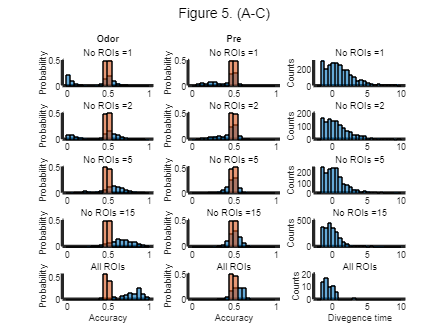

%{
Figure 5.A-C
A. Histogram for stimulus decoding accuracy calculated in the odor period (3.1 to 4.1 sec) for all proficient sessions (66 sessions) 
for 4 mice. i to v show the histogram for an increasing number of ROIs per decoding session. Blue is stimulus decoding accuracy, 
brown is stimulus decoding accuracy calculated after shuffling the labels. Histograms were normalized by dividing by the total 
number of counts.
B. Histograms calculated in the Pre period (-1 to 0 sec)
C. 
%}
%
%Plot accurcy histograms and do glm
%{
Setting constant values
%}
all_no_ROIs=[1 2 5 15 2000];
edges= 0:0.05:1;
loca_A = [1,4,7,10,13];
includeNum = 70;
epoch_labels{1}='Pre';
epoch_labels{2}='Odor';

figure();
for ii_ROI_choices=1:length(all_no_ROIs)
    subplot(length(all_no_ROIs),3,loca_A(ii_ROI_choices))
    ax=gca;
    ax.LineWidth=3;
    hold on
    all_accs=[];
    all_accs_sh=[];
    for fileNo=1:includeNum-1
        if fileNo < 10
            name_session = append("session_0",num2str(fileNo));
        else
            name_session = append("session_",num2str(fileNo));
        end
        this_time_span =FigureFive.(name_session).(name_ROI(ii_ROI_choices)).time_span;
        these_accs =FigureFive.(name_session).(name_ROI(ii_ROI_choices)).accuracy_per_ROI;
        these_accs_sh =FigureFive.(name_session).(name_ROI(ii_ROI_choices)).accuracy_per_ROI_sh;
        vetted_accs=nan(size(these_accs));
        vetted_accs_sh=nan(size(these_accs));
        ii_v=0;
        for ii_repeats=1:length(these_accs)
            %accuracy above 0.5
            this_acc_time_course = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}';

            if mean(this_acc_time_course(this_time_span<-2))<0.53
                ii_v=ii_v+1;
                vetted_accs(ii_v)=these_accs(ii_repeats);
                vetted_accs_sh(ii_v)=these_accs_sh(ii_repeats);
            end
        end
        vetted_accs = vetted_accs(~isnan(vetted_accs));
        vetted_accs_sh = vetted_accs_sh(~isnan(vetted_accs_sh));
        if ~isempty(vetted_accs)
            all_accs=[all_accs vetted_accs]; %#ok<AGROW>
            all_accs_sh=[all_accs_sh vetted_accs_sh]; %#ok<AGROW>
        end
    end
    histogram(all_accs,edges,'Normalization','Probability')
    histogram(all_accs_sh,edges,'Normalization','Probability')
    if ii_ROI_choices~=length(all_no_ROIs)
        if ii_ROI_choices == 1
            title('Odor')
        end
        subtitle(['No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
    else
        subtitle('All ROIs')
    end
    if ii_ROI_choices==5
        xlabel('Accuracy')
    end
    ylabel('Probability')
    hold("off")
end
%Fig. 8B
edges= 0:0.05:1 ;
loca_B = [2,5,8,11,14];
for ii_ROI_choices=1:length(all_no_ROIs)
    subplot(length(all_no_ROIs),3,loca_B(ii_ROI_choices))
    ax=gca;ax.LineWidth=3;
    hold on
    all_accs=[];
    all_accs_sh=[];
    for fileNo=1:includeNum
        if fileNo < 10
            name_session = append("session_0",num2str(fileNo));
        else
            name_session = append("session_",num2str(fileNo));
        end
        this_time_span=FigureFive.(name_session).(name_ROI(ii_ROI_choices)).time_span;
        these_accs=FigureFive.(name_session).(name_ROI(ii_ROI_choices)).accuracy_per_ROI_pre;
        these_accs_sh=FigureFive.(name_session).(name_ROI(ii_ROI_choices)).accuracy_per_ROI_sh_pre;
        vetted_accs=nan(size(these_accs));
        vetted_accs_sh=nan(size(these_accs));
        ii_v=0;
        for ii_repeats=1:length(these_accs)
            %accuracy above 0.5
            this_acc_time_course = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}';
            if mean(this_acc_time_course(this_time_span<-2))<0.53
                ii_v=ii_v+1;
                vetted_accs(ii_v)=these_accs(ii_repeats);
                vetted_accs_sh(ii_v)=these_accs_sh(ii_repeats);
            end
        end
        vetted_accs = vetted_accs(~isnan(vetted_accs));
        vetted_accs_sh = vetted_accs_sh(~isnan(vetted_accs_sh));
        if ~isempty(vetted_accs)
            all_accs=[all_accs vetted_accs]; %#ok<AGROW>
            all_accs_sh=[all_accs_sh vetted_accs_sh]; %#ok<AGROW>
            if ~isempty(vetted_accs)
                all_accs=[all_accs vetted_accs]; %#ok<AGROW>
                all_accs_sh=[all_accs_sh vetted_accs_sh]; %#ok<AGROW>
            end
        end

    end
    histogram(all_accs,edges,'Normalization','Probability')
    histogram(all_accs_sh,edges,'Normalization','Probability')
    if ii_ROI_choices~=length(all_no_ROIs)
        if ii_ROI_choices == 1
            title('Pre')
        end
        subtitle(['No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
    else
        subtitle('All ROIs')
    end
    if ii_ROI_choices==5
        xlabel('Accuracy')
    end
    ylabel('Probability')
    hold("off")
end
%Fig. 8C
id_lat_ii=0;
edges= -2:0.5:10 ;
loca_B = [3,6,9,12,15];
all_lats_per_ROI_choice=[];
for ii_ROI_choices=1:length(all_no_ROIs)
    subplot(length(all_no_ROIs),3,loca_B(ii_ROI_choices))
    ax=gca;ax.LineWidth=3;
    hold on
    all_lats=[];
    for fileNo=1:includeNum-1
        if fileNo < 10
            name_session = append("session_0",num2str(fileNo));
        else
            name_session = append("session_",num2str(fileNo));
        end
        these_lats = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).latency_per_ROI;
        this_time_span = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).time_span;
        vetted_lats=nan(size(these_lats));
        ii_v=0;
        for ii_repeats=1:length(these_lats)
            %accuracy above 0.5
            this_acc_time_course = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}';
            if (mean(this_acc_time_course(this_time_span<-2))<0.53) && (~isnan(these_lats(ii_repeats)))
                ii_v=ii_v+1;
                vetted_lats(ii_v)=these_lats(ii_repeats);
            end
        end
        vetted_lats = vetted_lats(~isnan(vetted_lats));
        if ~isempty(vetted_lats)
            all_lats=[all_lats vetted_lats]; %#ok<AGROW>
        end
    end
    histogram(all_lats,edges)
    if ii_ROI_choices~=length(all_no_ROIs)
        subtitle(['No ROIs =', num2str(all_no_ROIs(ii_ROI_choices))])
    else
        subtitle('All ROIs')
    end
    if ii_ROI_choices==5
        xlabel('Divegence time')
    end
    ylabel('Counts')
    hold("off")
end
sgtitle('Figure 5. (A-C)')
hold off

Figure 5.D

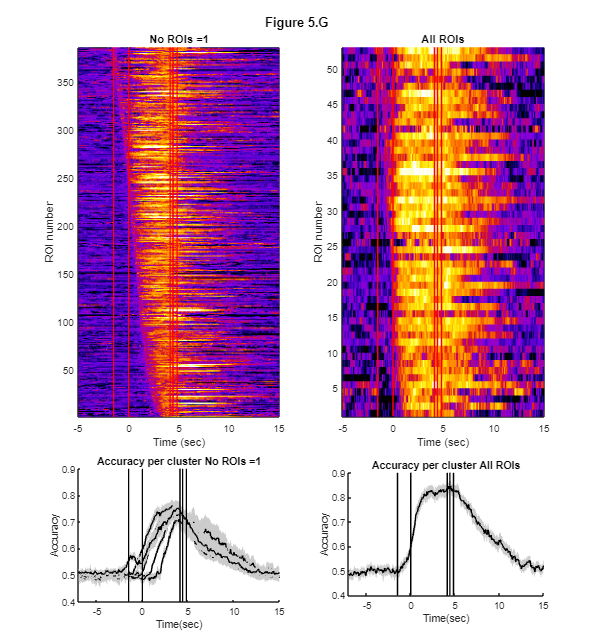


%{
Figure 5.D
(i). Time courses for decoding accuracies calculated with one ROI per session that reach at least 0.65 after 
trial start. 
(ii) Mean accuracy time courses calculated for one ROI accuracy time courses shown in Di with 
accuracy increase onsets in the following time windows: -1.5 to -1, -1 to 0, 0 to 1, 1 to 2, 2 to 3, >3 sec. 
(iii) Time courses for decoding accuracies calculated all ROIs per session. 
(iv) Mean accuracy time course for the time courses shown in Diii
%}
hFig = figure();
hFig.Position(1) = hFig.Position(1) + 350;
hFig.Position(2) = hFig.Position(2) + 550;
hFig.Position(3) = hFig.Position(3) + 350;
hFig.Position(4) = hFig.Position(4) + 550;

% Time events of interest (e.g. stimulus onset/offset, cues etc.)
% They are marked on the plots with vertical lines
delta_odor=4.127634e+00;
delta_odor_on_reinf_on=4.415787e+00;
delta_reinf=4.078266e-01;
timeEvents = [-1.5 0 delta_odor delta_odor_on_reinf_on delta_reinf+delta_odor_on_reinf_on];
acc_thr=[0.35 0.65];
cluster_times=[-1.5 -1;-1 0; 0 1; 1 2; 2 3; 3 200];
%Plot the pseudocolor time courses

time_span = FigureFive.session_01.ROI_1.time_span;



subplot(4,2,1:2)
text(.4,.5,'Figure 5.G','FontSize',12,'FontWeight','bold'); axis off
ax = gca;
ax.Position(2) = ax.Position(2) + 0.12;

for ii_ROI_choices=1:length(all_no_ROIs)

    all_acc_time_courses=zeros(5000,length(time_span));
    all_acc_time_courses2=zeros(5000,length(time_span));
    all_lats_for_acc_time_courses=[];
    ii_included=0;
    for fileNo=1:includeNum-1

        if fileNo < 10
            name_session = append("session_0",num2str(fileNo));
        else
            name_session = append("session_",num2str(fileNo));
        end
        these_accs=FigureFive.(name_session).(name_ROI(ii_ROI_choices)).accuracy_per_ROI;
        these_lats=FigureFive.(name_session).(name_ROI(ii_ROI_choices)).latency_per_ROI;

        for ii_repeats=1:length(these_accs)
            if these_accs(ii_repeats)>=acc_thr(2)

                this_time_span = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).time_span;
                this_acc_time_course = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}';

                %NOte: some of the noisy traces yield artifactual
                %accuracy above 0.5
                if mean(this_acc_time_course(this_time_span<-2))<0.53
                    ii_included=ii_included+1;
                    all_lats_for_acc_time_courses(ii_included)=these_lats(ii_repeats);

                    resample=0;
                    if length(this_time_span)~=length(time_span)
                        resample=1;
                    else
                        if sum(time_span==this_time_span)~=length(time_span)
                            resample=1;
                        end
                    end
                    if resample==0
                        all_acc_time_courses(ii_included,:) = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}';

                    else
                        %Resample
                        for ii_t=1:length(time_span)
                            if time_span(ii_t)<this_time_span(1)
                                all_acc_time_courses(ii_included,ii_t) = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}(1);

                            else
                                if time_span(ii_t)>this_time_span(end)
                                    all_acc_time_courses(ii_included,ii_t) = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}(end);

                                else
                                    if isempty(find(time_span(ii_t)==this_time_span,1))
                                        ii_before=find(this_time_span<time_span(ii_t),1,'last');
                                        ii_after=find(this_time_span>time_span(ii_t),1,'first');

                                        acc_before = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}(ii_before)';
                                        acc_after = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats,1}(ii_after)';

                                        all_acc_time_courses(ii_included,ii_t)= acc_before+(acc_after-acc_before)*(time_span(ii_t)-this_time_span(ii_before))/(this_time_span(ii_after)-this_time_span(ii_before));
                                    else
                                        ii_found=find(time_span(ii_t)==this_time_span,1,'first');

                                        all_acc_time_courses(ii_included,ii_t) = FigureFive.(name_session).(name_ROI(ii_ROI_choices)).mean_accuracy.mean_average{ii_repeats}(ii_found)';

                                    end
                                end
                            end
                        end
                    end
                end
            end
        end
    end


    all_acc_time_courses(ii_included+1:end,:)=[];


    %Sort by diverging time
    to_sort=[all_lats_for_acc_time_courses' (1:ii_included)'];
    sorted=sortrows(to_sort);
    outperm=sorted(:,2);



    clusters = nan(size(all_lats_for_acc_time_courses));
    for ii_tc=1:length(all_lats_for_acc_time_courses)
        for clus=1:size(cluster_times,1)
            if (all_lats_for_acc_time_courses(ii_tc)>=cluster_times(clus,1)) && (all_lats_for_acc_time_courses(ii_tc)<=cluster_times(clus,2))
                clusters(ii_tc)=clus;
            end
        end
    end
    if ii_ROI_choices == 1 || ii_ROI_choices == 5
        %Plot timecourses for all accuracy time courses

        if ii_ROI_choices == 1
            subplot(4,2,[3,5])
        elseif ii_ROI_choices == 5
            subplot(4,2,[4,6])

        end

        sorted_handles_out.all_acc_time_courses=[];
        sorted_handles_out.clusters=[];
        for ii=1:ii_included
            sorted_handles_out.all_acc_time_courses(ii_included-ii+1,:)=all_acc_time_courses(outperm(ii),:);
            sorted_handles_out.clusters(ii_included-ii+1)=clusters(outperm(ii));
        end

        %pcolor does not show the first row
        pseudo_acc=zeros(size(sorted_handles_out.all_acc_time_courses,1)+1,size(sorted_handles_out.all_acc_time_courses,2));
        pseudo_acc(1:end-1,:)=sorted_handles_out.all_acc_time_courses;

        time_span_mat=repmat(time_span,ii_included+1,1);
        ROI_mat=repmat(1:ii_included+1,length(time_span),1)';

        pcolor(time_span_mat,ROI_mat,pseudo_acc)
        hold('on')


        shading flat
        clim([0.4,1])

        for ii_te=1:length(timeEvents)
            plot([timeEvents(ii_te) timeEvents(ii_te)],[0 ii_included],'-r')
        end

        xlim([-5 15])
        ylim([1 ii_included])
        if ii_ROI_choices~=length(all_no_ROIs)
            title(['No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
        else
            title('All ROIs')
        end
        xlabel('Time (sec)')
        ylabel('ROI number')
        ax = gca;
        ax.Position(2) = ax.Position(2) + 0.02;
        ax.Position(4) = ax.Position(4) + 0.2;
        colormap fire
    end

    if ii_ROI_choices == 1
        %Plot the average timecourses per cluster

        hold('off')
        subplot(4,2,7)

        hold('on')
        for clus=max(clusters):-1:1
            %plot the accuracies
            this_cluster_acc=[];
            ii_inc=0;
            for ii=1:length(sorted_handles_out.clusters)
                if sorted_handles_out.clusters(ii)==clus
                    ii_inc=ii_inc+1;
                    this_cluster_acc(ii_inc,:)=sorted_handles_out.all_acc_time_courses(ii,:);
                end
            end

            if ii_inc>=5
                CIpv = bootci(1000, @mean, this_cluster_acc);
                meanpv=mean(this_cluster_acc,1);
                CIpv(1,:)=meanpv-CIpv(1,:);
                CIpv(2,:)=CIpv(2,:)-meanpv;


                [hlpvl, hppvl] = boundedline(time_span,mean(this_cluster_acc), CIpv','cmap',[0 0 0]);


            end

        end

        ylim([0.4 0.9])
        this_ylim=ylim;
        for ii_te=1:length(timeEvents)
            plot([timeEvents(ii_te) timeEvents(ii_te)],this_ylim,'-k')
        end

        xlim([-7 15])


        xlabel('Time(sec)')
        ylabel('Accuracy')
        ax = gca;
        ax.Position(2) = ax.Position(2) - 0.05;
        ax.Position(4) = ax.Position(4) + 0.05;
        title(['Accuracy per cluster No ROIs =' num2str(all_no_ROIs(ii_ROI_choices))])
    end
    %Plot average of all traces
    if ii_ROI_choices == 5

        hold('off')
        subplot(4,2,8)

        hold('on')

        CIpv = bootci(1000, @mean, sorted_handles_out.all_acc_time_courses);
        meanpv=mean(sorted_handles_out.all_acc_time_courses,1);
        CIpv(1,:)=meanpv-CIpv(1,:);
        CIpv(2,:)=CIpv(2,:)-meanpv;


        [hlpvl, hppvl] = boundedline(time_span,mean(sorted_handles_out.all_acc_time_courses), CIpv','cmap',[0 0 0]);
        ylim([0.4 0.9])
        this_ylim=ylim;
        for ii_te=1:length(timeEvents)
            plot([timeEvents(ii_te) timeEvents(ii_te)],this_ylim,'-k')
        end
        xlim([-7 15])
        xlabel('Time(sec)')
        ylabel('Accuracy')
        ax = gca;
        ax.OuterPosition(2) = ax.OuterPosition(2) - 0.05;
        ax.OuterPosition(4) = ax.OuterPosition(4) + 0.06;
        title('Accuracy per cluster All ROIs')
    end
end

Figure 6

Figure 7